## Load Measurement Data

%%%%%%%%%% DELETE FOR REAL MEASUREMENT, BOZO %%%%%%%%%%%%%%%%
yData = randn(1000,1);
uData = randn(1000,1);
save FRF yData uData 
clear all;
%%%%%%%%%% DELETE FOR REAL MEASUREMENT, BOZO %%%%%%%%%%%%%%%%


measurement = load("FRF.mat");
FRF.u = measurement.uData;
FRF.y = measurement.yData;
%% Measurement Constants
fs = 10;                               %% Insert actual sampling freq! 
Ts = 1/fs;
L = length(FRF.u);

## Take FFT of both signals

FFT.u = fft(FRF.u);
FFT.y = fft(FRF.y);


## Estimate H(f)

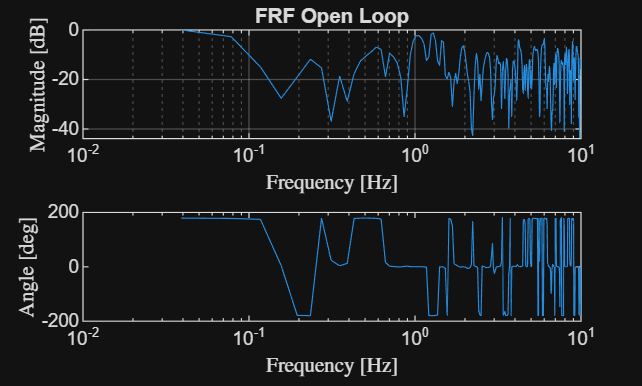

%% PSD/CPSD Constants
noverlap = 10;                                 %% Nr of overlapped samples [# samples]
nfft = 100;                                    %% Window length [# samples]

[H,hz] = tfestimate(FFT.u,FFT.y,hann(nfft),noverlap,[],fs);
%% plot FRF
mag = 20*log10(abs(H));
ph = angle(H) * (180/pi);
figure;
subplot(2,1,1)
semilogx(hz,mag);
title("FRF Open Loop")
grid on;
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Magnitude [dB]',Interpreter="latex")
subplot(2,1,2)
semilogx(hz,ph)
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Angle [deg]',Interpreter="latex")


freqRes = fs/nfft

freqRes = 0.1000